# MSS - module 2

# Written exam 2025/07/09

## Modelling part

### Exercise 1

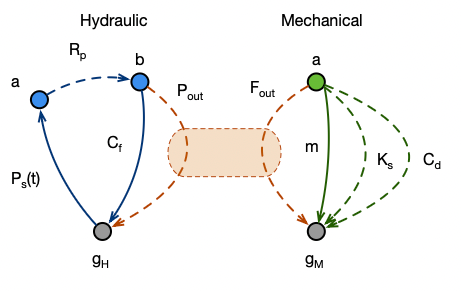

Compute the 

- Incidence matrix

- node and loop equations

- consitutive equations

- final set of hydraulic system of equations

clear 

% Definitions of through variables
syms t Q_s(t) Q_Rp(t) Q_f(t) Q_out(t) F_out(t) F_m(t) F_s(t) F_d(t)
syms   P_s(t) P_Rp(t) P_f(t) P_out(t) v_out(t) v_m(t) v_s(t) v_d(t)

% Hydraulic system - - - - - - - - - - - - - - - - - - - - - - - - - 
% through and across variables
tau_H   = [Q_s(t); Q_Rp(t); Q_f(t)] %; Q_out(t)];

$$tau\_H = \left(\begin{array}{c} Q_{s}\left(t\right)\\ Q_{\mathrm{Rp}}\left(t\right)\\ Q_{f}\left(t\right) \end{array}\right)$$

alpha_H = [P_s(t); P_Rp(t); P_f(t)] %;  P_out(t)];

$$alpha\_H = \left(\begin{array}{c} P_{s}\left(t\right)\\ P_{\mathrm{Rp}}\left(t\right)\\ P_{f}\left(t\right) \end{array}\right)$$


% Branch through coordinates
tau_Hb   = [Q_s(t); Q_f(t) ];
alpha_Hb = [P_s(t); P_f(t) ];

% Chord through coordinates
tau_Hc   =[  Q_Rp(t); Q_out(t)];
alpha_Hc =[  P_Rp(t); P_out(t)];

nb_H = 2;
ne_H = 4;

% Mechanical system - - - - - - - - - - - - - - - - - - - - - - - - - 
% through and across variables
tau_M   = [F_m(t); F_s(t); F_d(t); F_out(t)];
alpha_M = [v_m(t); v_s(t); v_d(t); v_out(t)];

% Branch through coordinates
tau_Mb   = [F_m(t)];
alpha_Mb = [v_m(t)];

% Chord through coordinates
tau_Mc   = [F_s(t); F_d(t); F_out(t)];
alpha_Mc = [v_s(t); v_d(t); v_out(t)];

nb_M = 1;
ne_M = 4;


System parameters

% definition of parameters
syms C_f R_p C_d A beta m K_s C_d

#### Hydraulic 

Reduced Incidence matrix

% Q_s(t);  Q_f(t);  Q_Rp(t); Q_out(t)
IM_H = sym( ...
         [+1  0 -1 0 ;...
           0 -1  1 -1; ...
          -1 +1  0 +1 ...
           ]);
% reduced matrix
A_H= IM_H(1:nb_H,1:end)

$$A\_H = \left(\begin{array}{cccc} 1 & 0 & -1 & 0\\ 0 & -1 & 1 & -1 \end{array}\right)$$

Echelon form of reduced incidence matrix

A_Hf=rref(A_H) % [Ib | Ac]

$$A\_Hf = \left(\begin{array}{cccc} 1 & 0 & -1 & 0\\ 0 & 1 & -1 & 1 \end{array}\right)$$

Ac_H = A_Hf(1:nb_H,nb_H+1:ne_H)

$$Ac\_H = \left(\begin{array}{cc} -1 & 0\\ -1 & 1 \end{array}\right)$$

Orthogonal matrix 

Bb_H = Ac_H.'  % [Ab, Ic]

$$Bb\_H = \left(\begin{array}{cc} -1 & -1\\ 0 & 1 \end{array}\right)$$

**Loop equations**

loop_eqns_H = alpha_Hc == -Bb_H*alpha_Hb

$$loop\_eqns\_H = \left(\begin{array}{c} P_{\mathrm{Rp}}\left(t\right)=P_{f}\left(t\right)+P_{s}\left(t\right)\\ P_{\mathrm{out}}\left(t\right)=-P_{f}\left(t\right) \end{array}\right)$$

**Node equations**

node_eqns_H =  tau_Hb == -Ac_H*tau_Hc

$$node\_eqns\_H = \left(\begin{array}{c} Q_{s}\left(t\right)=Q_{\mathrm{Rp}}\left(t\right)\\ Q_{f}\left(t\right)=Q_{\mathrm{Rp}}\left(t\right)-Q_{\mathrm{out}}\left(t\right) \end{array}\right)$$

**Constitutive equations**

syms f(t)

const_eqns= [
    C_f*diff(P_f(t),t) ==  Q_f(t);
    P_Rp(t) == R_p*Q_Rp(t);
    P_s(t) == f(t);
    F_out(t) == A*Q_f(t);
    Q_out(t) == A*v_m(t)
    ]

$$const\_eqns = \left(\begin{array}{c} C_{f}\,\frac{\partial }{\partial t}P_{f}\left(t\right)=Q_{f}\left(t\right)\\ P_{\mathrm{Rp}}\left(t\right)=R_{p}\,Q_{\mathrm{Rp}}\left(t\right)\\ P_{s}\left(t\right)=f\left(t\right)\\ F_{\mathrm{out}}\left(t\right)=A\,Q_{f}\left(t\right)\\ Q_{\mathrm{out}}\left(t\right)=A\,v_{m}\left(t\right) \end{array}\right)$$

%P_out(t) == R_out*Q_out(t);
tmp0 = subs(const_eqns,num2cell(lhs(loop_eqns_H)),num2cell(rhs(loop_eqns_H)))  

$$tmp0 = \left(\begin{array}{c} C_{f}\,\frac{\partial }{\partial t}P_{f}\left(t\right)=Q_{f}\left(t\right)\\ P_{f}\left(t\right)+P_{s}\left(t\right)=R_{p}\,Q_{\mathrm{Rp}}\left(t\right)\\ P_{s}\left(t\right)=f\left(t\right)\\ F_{\mathrm{out}}\left(t\right)=A\,Q_{f}\left(t\right)\\ Q_{\mathrm{out}}\left(t\right)=A\,v_{m}\left(t\right) \end{array}\right)$$

dae_H= subs(tmp0,num2cell(lhs(node_eqns_H)),num2cell(rhs(node_eqns_H)))

$$dae\_H = \left(\begin{array}{c} C_{f}\,\frac{\partial }{\partial t}P_{f}\left(t\right)=Q_{\mathrm{Rp}}\left(t\right)-Q_{\mathrm{out}}\left(t\right)\\ P_{f}\left(t\right)+P_{s}\left(t\right)=R_{p}\,Q_{\mathrm{Rp}}\left(t\right)\\ P_{s}\left(t\right)=f\left(t\right)\\ F_{\mathrm{out}}\left(t\right)=A\,\left(Q_{\mathrm{Rp}}\left(t\right)-Q_{\mathrm{out}}\left(t\right)\right)\\ Q_{\mathrm{out}}\left(t\right)=A\,v_{m}\left(t\right) \end{array}\right)$$

Define the vector of algebraic variables

alg_vars_H = [P_s(t),F_out(t),Q_out(t),Q_Rp(t)]

$$alg\_vars\_H = \left(\begin{array}{cccc} P_{s}\left(t\right) & F_{\mathrm{out}}\left(t\right) & Q_{\mathrm{out}}\left(t\right) & Q_{\mathrm{Rp}}\left(t\right) \end{array}\right)$$

Define vector of algebraic variables for substitution

a = sym("a",[1 4])

$$a = \left(\begin{array}{cccc} a_{1} & a_{2} & a_{3} & a_{4} \end{array}\right)$$

Solve system of algebraic variables


S_H=solve(subs([dae_H(2:5)],num2cell(alg_vars_H),num2cell(a)),a)

S_H = struct with fields:
    a1: f(t)
    a2: (A*(P_f(t) + f(t) - A*R_p*v_m(t)))/R_p
    a3: A*v_m(t)
    a4: (P_f(t) + f(t))/R_p


alg_vars_H.' == [ S_H.a1;S_H.a2;S_H.a3;S_H.a4]

$$ans = \left(\begin{array}{c} P_{s}\left(t\right)=f\left(t\right)\\ F_{\mathrm{out}}\left(t\right)=\frac{A\,\left(P_{f}\left(t\right)+f\left(t\right)-A\,R_{p}\,v_{m}\left(t\right)\right)}{R_{p}}\\ Q_{\mathrm{out}}\left(t\right)=A\,v_{m}\left(t\right)\\ Q_{\mathrm{Rp}}\left(t\right)=\frac{P_{f}\left(t\right)+f\left(t\right)}{R_{p}} \end{array}\right)$$

Substitute in the remaining equation and obtain the ode. The pressure (or height) of the tank is a function of the punm flow rate and the output flow rate which are two given functions

ode_H= subs(dae_H(1),num2cell(alg_vars_H),num2cell([ S_H.a1 S_H.a2 S_H.a3 S_H.a4]))

$$ode\_H = C_{f}\,\frac{\partial }{\partial t}P_{f}\left(t\right)=\frac{P_{f}\left(t\right)+f\left(t\right)}{R_{p}}-A\,v_{m}\left(t\right)$$

#### Mechanical 

Reduced Incidence matrix

% F_m(t); F_s(t); F_d(t); F_out(t)
IM_M = sym( ...
         [-1 -1 -1 -1;...
          +1 +1 +1 +1 ...
           ]);
% reduced matrix
A_M= IM_M(1:nb_M,1:end)

$$A\_M = \left(\begin{array}{cccc} -1 & -1 & -1 & -1 \end{array}\right)$$

Echelon form of reduced incidence matrix

A_Mf=rref(A_M) % [Ib | Ac]

$$A\_Mf = \left(\begin{array}{cccc} 1 & 1 & 1 & 1 \end{array}\right)$$

Ac_M = A_Mf(1:nb_M,nb_M+1:ne_M)

$$Ac\_M = \left(\begin{array}{ccc} 1 & 1 & 1 \end{array}\right)$$

Orthogonal matrix 

Bb_M = Ac_M.'  % [Ab, Ic]

$$Bb\_M = \left(\begin{array}{c} 1\\ 1\\ 1 \end{array}\right)$$

**Loop equations**

loop_eqns_M = alpha_Mc == -Bb_M*alpha_Mb

$$loop\_eqns\_M = \left(\begin{array}{c} v_{s}\left(t\right)=-v_{m}\left(t\right)\\ v_{d}\left(t\right)=-v_{m}\left(t\right)\\ v_{\mathrm{out}}\left(t\right)=-v_{m}\left(t\right) \end{array}\right)$$

**Node equations**

node_eqns_M =  tau_Mb == -Ac_M*tau_Mc

$$node\_eqns\_M = F_{m}\left(t\right)=-F_{d}\left(t\right)-F_{\mathrm{out}}\left(t\right)-F_{s}\left(t\right)$$

**Constitutive equations**

syms f(t)  s(t)

const_eqns_M= [
    m*diff(v_m(t),t) ==  F_m(t);
    diff(s(t),t) == v_s(t);
    F_s(t) == K_s*s(t);
    F_d(t) == C_d*v_d(t);
    %F_out(t) == A*Q_f(t); % already added in hydraulic branch
    %Q_out(t) == A*v_m(t)  % already added in hydraulic branch
    ]

$$const\_eqns\_M = \left(\begin{array}{c} m\,\frac{\partial }{\partial t}v_{m}\left(t\right)=F_{m}\left(t\right)\\ \frac{\partial }{\partial t}s\left(t\right)=v_{s}\left(t\right)\\ F_{s}\left(t\right)=K_{s}\,s\left(t\right)\\ F_{d}\left(t\right)=C_{d}\,v_{d}\left(t\right) \end{array}\right)$$

tmp0 = subs(const_eqns_M,num2cell(lhs(loop_eqns_M)),num2cell(rhs(loop_eqns_M)))  ;
dae_M= subs(tmp0,num2cell(lhs(node_eqns_M)),num2cell(rhs(node_eqns_M)))

$$dae\_M = \left(\begin{array}{c} m\,\frac{\partial }{\partial t}v_{m}\left(t\right)=-F_{d}\left(t\right)-F_{\mathrm{out}}\left(t\right)-F_{s}\left(t\right)\\ \frac{\partial }{\partial t}s\left(t\right)=-v_{m}\left(t\right)\\ F_{s}\left(t\right)=K_{s}\,s\left(t\right)\\ F_{d}\left(t\right)=-C_{d}\,v_{m}\left(t\right) \end{array}\right)$$

### Exercise 2

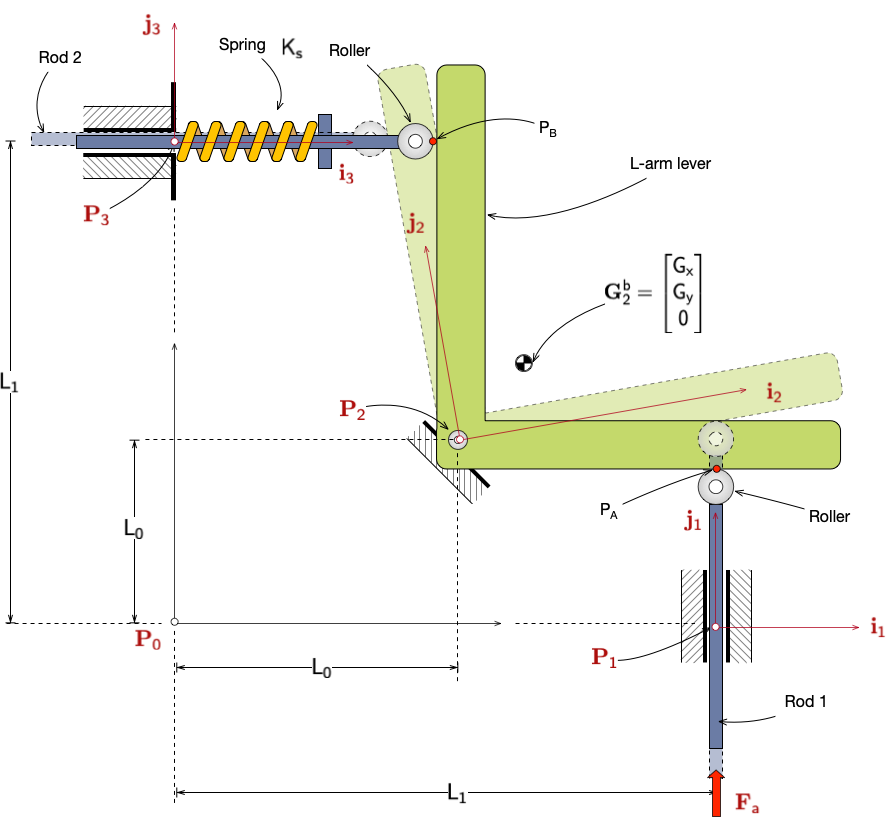

Compute the 

- LG + normal tree

- T-Graph and loop equations

- Node equations

- Newton Euler equations


clear all
clear;
addpath('../MBsLib_v2_1/')

#### Linear Graph and normal tree

The LG shows that the Multibody system is made of 2 prismatic joint, one revolute joint and two cam joints.

The cam joints are the cut joints. LG shows also the points of application of  actuation forces.

NB: please note that the edges of body G2 and weight of body G2 are not displaed in the LG.

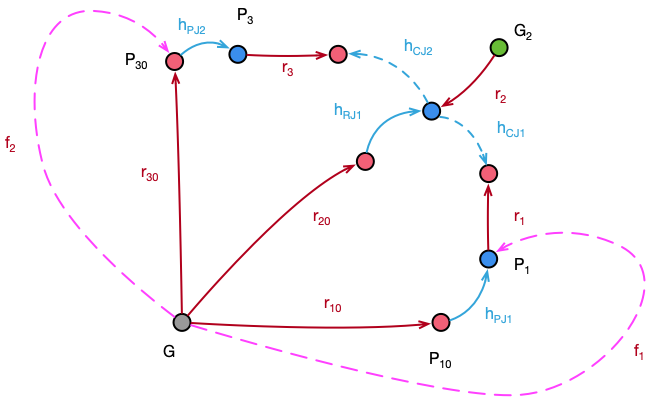

The normal tree contains the joint: {revolute joint RJ1, prismatic joint PJ1 and prismatic joint PJ2}. The corresponding branch coordinates are 


$$\mathbf{q}=\{\theta_1(t),s_1(t),s_2(t)\}$$


The cam joints are the cut joints where loop equations are defined.

**Note: the positions of the contact points of the cam joints along the L-shaped body arms are not explicitly defined by variables. One may decide to use also those additional variables, but they are not necessary** 

Definition of variables and parameters

syms  theta_1(t) s_1(t) s_2(t)

% Parameters
syms L_0 L_1 G_x G_y

We next define the joint matrices and the vectors (edges) of the T-graph

% Transformation matrix of Prismatic joints
R1 = translate([0,s_1(t),0])

$$R1 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & s_{1}\left(t\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

r_pj1 = R1(:,4)-[0;0;0;1]; % vector prismatic joint
% Transformation matrix of Prismatic joints
R3 = translate([s_2(t),0,0])

$$R3 = \left(\begin{array}{cccc} 1 & 0 & 0 & s_{2}\left(t\right)\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

r_pj3 = R3(:,4)-[0;0;0;1] % vector prismatic joint

$$r\_pj3 = \left(\begin{array}{c} s_{2}\left(t\right)\\ 0\\ 0\\ 0 \end{array}\right)$$


% Rotation matrix of Revolute joints
R2 = rotate("Z",theta_1(t))

$$R2 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\left(t\right)\right) & -\sin\left(\theta_{1}\left(t\right)\right) & 0 & 0\\ \sin\left(\theta_{1}\left(t\right)\right) & \cos\left(\theta_{1}\left(t\right)\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

r_rj2 = R2(:,4)-[0;0;0;1]; % vector revolute joint

% Position in world frame of revolute joint in P1
r10 = [L_1;0;0;0];

% Position in world frame of revolute joint in P2
r20 = [L_0;L_0;0;0];

% Position in world frame of revolute joint in P3
r30 = [0;L_1;0;0];

% Vector in world frame of point PA
r1 = R1*[0;L_0;0;0];

% Vector in world frame of point PB
r3 = R1*[L_0;0;0;0];

% Vector in world frame of point G2
rG2 = -R2*[G_x;G_y;0;0];

#### Loop equations

% Vector between point P2 and PB
r2B = r30+r_pj3+r3-(r20+r_rj2)

$$r2B = \left(\begin{array}{c} s_{2}\left(t\right)\\ L_{1}-L_{0}\\ 0\\ 0 \end{array}\right)$$

We project the vector in the constraint **reaction space**. That is in the direction of unit vector i2 where the relative motion cannot occur. The projection in the motion space (instead), defines the coordiates of the position of the contact point PB in the y-axis of the L-shaped body. In this case we do not use it.

% Projection in reaction space
i2 = R2(:,1); % get_unit_vector("X",R2)
loop_eq1 = r2B.'*i2 == 0

$$loop\_eq1 = \cos\left(\theta_{1}\left(t\right)\right)\,s_{2}\left(t\right)-\sin\left(\theta_{1}\left(t\right)\right)\,\left(L_{0}-L_{1}\right)=0$$

% Vector between point P1 and PA
r1A = r10+r_pj1+r1-(r20+r_rj2)

$$r1A = \left(\begin{array}{c} L_{1}-L_{0}\\ s_{1}\left(t\right)\\ 0\\ 0 \end{array}\right)$$

% Projection in reaction space
j2 = R2(:,2); % get_unit_vector("Y",R2)
loop_eq2 = r1A.'*j2 == 0

$$loop\_eq2 = \sin\left(\theta_{1}\left(t\right)\right)\,\left(L_{0}-L_{1}\right)+\cos\left(\theta_{1}\left(t\right)\right)\,s_{1}\left(t\right)=0$$

#### Positions of points

% Position of centre of mass
G2 = r20+r_rj2-rG2

$$G2 = \left(\begin{array}{c} L_{0}-G_{y}\,\sin\left(\theta_{1}\left(t\right)\right)+G_{x}\,\cos\left(\theta_{1}\left(t\right)\right)\\ L_{0}+G_{x}\,\sin\left(\theta_{1}\left(t\right)\right)+G_{y}\,\cos\left(\theta_{1}\left(t\right)\right)\\ 0\\ 0 \end{array}\right)$$

% Velocity
syms theta_dot1(t)

% Reduce also to first order
eq_theta_dot = diff(theta_1(t),t)-theta_dot1(t)==0

$$eq\_theta\_dot = \frac{\partial }{\partial t}\theta_{1}\left(t\right)-\theta_{\mathrm{dot1}}\left(t\right)=0$$

VG2 = subs( diff(G2,t),[diff(theta_1(t),t)],[theta_dot1(t)])

$$VG2 = \left(\begin{array}{c} -G_{y}\,\cos\left(\theta_{1}\left(t\right)\right)\,\theta_{\mathrm{dot1}}\left(t\right)-G_{x}\,\sin\left(\theta_{1}\left(t\right)\right)\,\theta_{\mathrm{dot1}}\left(t\right)\\ G_{x}\,\cos\left(\theta_{1}\left(t\right)\right)\,\theta_{\mathrm{dot1}}\left(t\right)-G_{y}\,\sin\left(\theta_{1}\left(t\right)\right)\,\theta_{\mathrm{dot1}}\left(t\right)\\ 0\\ 0 \end{array}\right)$$

% Acceleration
AG2 = subs( diff(VG2,t),[diff(theta_1(t),t)],[theta_dot1(t)])

$$AG2 = \left(\begin{array}{c} G_{y}\,\sin\left(\theta_{1}\left(t\right)\right)\,{\theta_{\mathrm{dot1}}\left(t\right)}^{2}-G_{x}\,\cos\left(\theta_{1}\left(t\right)\right)\,{\theta_{\mathrm{dot1}}\left(t\right)}^{2}-G_{y}\,\cos\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{\mathrm{dot1}}\left(t\right)-G_{x}\,\sin\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{\mathrm{dot1}}\left(t\right)\\ G_{x}\,\cos\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{\mathrm{dot1}}\left(t\right)-G_{x}\,\sin\left(\theta_{1}\left(t\right)\right)\,{\theta_{\mathrm{dot1}}\left(t\right)}^{2}-G_{y}\,\cos\left(\theta_{1}\left(t\right)\right)\,{\theta_{\mathrm{dot1}}\left(t\right)}^{2}-G_{y}\,\sin\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{\mathrm{dot1}}\left(t\right)\\ 0\\ 0 \end{array}\right)$$

**Spring vector**

The spring deformations is directly given by the primstai joint coordinates if the the normal length of the spring corresponds to L0.

% Horizontal spring
rs3 = r30+r_pj3+r3-r30

$$rs3 = \left(\begin{array}{c} L_{0}+s_{2}\left(t\right)\\ 0\\ 0\\ 0 \end{array}\right)$$

**Points**

P1 = r10+r_pj1; % in world coords
P2 = r20+r_rj2; % in world coords
P3 = r30+r_pj3; % in world coords

PA = r10+r_pj1+r1; % in world coords
PB = r30+r_pj3+r3; % in world coords

% Vector between G2 and PA and PB (Please not that PA and PB are projected in body coords)

VG2PA = inv_frame(R2)*(PA-G2); % in body frame
VG2PB = inv_frame(R2)*(PB-G2)  % in body frame

$$VG2PB = \begin{array}{l} \left(\begin{array}{c} \cos\left(\theta_{1}\left(t\right)\right)\,\sigma_{1}-\sin\left(\theta_{1}\left(t\right)\right)\,\sigma_{2}\\ -\sin\left(\theta_{1}\left(t\right)\right)\,\sigma_{1}-\cos\left(\theta_{1}\left(t\right)\right)\,\sigma_{2}\\ 0\\ 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=s_{2}\left(t\right)+G_{y}\,\sin\left(\theta_{1}\left(t\right)\right)-G_{x}\,\cos\left(\theta_{1}\left(t\right)\right)\\ \sigma_{2}=L_{0}-L_{1}+G_{x}\,\sin\left(\theta_{1}\left(t\right)\right)+G_{y}\,\cos\left(\theta_{1}\left(t\right)\right) \end{array}$$

VG2P2 = inv_frame(R2)*(PB-P2)  % in body frame

$$VG2P2 = \left(\begin{array}{c} \cos\left(\theta_{1}\left(t\right)\right)\,s_{2}\left(t\right)-\sin\left(\theta_{1}\left(t\right)\right)\,\left(L_{0}-L_{1}\right)\\ -\cos\left(\theta_{1}\left(t\right)\right)\,\left(L_{0}-L_{1}\right)-\sin\left(\theta_{1}\left(t\right)\right)\,s_{2}\left(t\right)\\ 0\\ 0 \end{array}\right)$$

### Newton Euler Equations

We consider only one body

#### Body balance (i.e. Node balance)

syms N_A(t) N_B(t) R_x(t) R_y(t) F_B2x(t) F_B2y(t) Rx_pj1(t) Ry_pj2(t) T_pj1(t) T_pj2(t) F_a(t) m g I_z2 K_s

% Joint reaction forces in world coordinates
F_CJ1 = R2*[0;N_A(t);0;0]; % cam joint 1
F_CJ2 = R2*[N_B(t);0;0;0]; % cam joint 2
F_RJ2 = [R_x(t);R_y(t);0;0]; % cam joint 2

FW = [0;-m*g;0;0]; % cam joint 2

FA = [0;F_a(t);0;0]; % actuation force
FS = -K_s*rs3 % spring force

$$FS = \left(\begin{array}{c} -K_{s}\,\left(L_{0}+s_{2}\left(t\right)\right)\\ 0\\ 0\\ 0 \end{array}\right)$$


F_PJ1 = [Rx_pj1(t);0;0;0]; % prismatic joint 1 reaction
T_PJ1 = [0;0;T_pj1(t);0]; % prismatic joint 1 reaction

F_PJ2 = [0;Ry_pj2(t);0;0]; % prismatic joint 2 reaction
T_PJ2 = [0;0;T_pj2(t);0]; % prismatic joint 2 reaction


**Balance of body 2**

**Translation (in world frame)**

%tmp = -[F_B2x(t); F_B2y(t);0;0]+F_CJ1+F_CJ2+F_RJ2+FW
FB2 = +F_CJ1+F_CJ2+F_RJ2+FW

$$FB2 = \left(\begin{array}{c} R_{x}\left(t\right)+\cos\left(\theta_{1}\left(t\right)\right)\,N_{B}\left(t\right)-\sin\left(\theta_{1}\left(t\right)\right)\,N_{A}\left(t\right)\\ R_{y}\left(t\right)-g\,m+\cos\left(\theta_{1}\left(t\right)\right)\,N_{A}\left(t\right)+\sin\left(\theta_{1}\left(t\right)\right)\,N_{B}\left(t\right)\\ 0\\ 0 \end{array}\right)$$

**Rotation (in body frame)**

TB2 = cross_prod2(VG2PA,inv_frame(R2)*F_CJ1)+cross_prod2(VG2PB,inv_frame(R2)*F_CJ2)+cross_prod2(VG2P2,inv_frame(R2)*F_RJ2)

$$TB2 = \begin{array}{l} \left(\begin{array}{c} 0\\ 0\\ R_{y}\left(t\right)\,s_{2}\left(t\right)-N_{A}\left(t\right)\,\left(G_{x}-\sin\left(\theta_{1}\left(t\right)\right)\,s_{1}\left(t\right)+\sigma_{2}-\sigma_{1}\right)+N_{B}\left(t\right)\,\left(G_{y}+\sin\left(\theta_{1}\left(t\right)\right)\,s_{2}\left(t\right)+\sigma_{2}-\sigma_{1}\right)+L_{0}\,R_{x}\left(t\right)-L_{1}\,R_{x}\left(t\right)\\ 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L_{1}\,\cos\left(\theta_{1}\left(t\right)\right)\\ \sigma_{2}=L_{0}\,\cos\left(\theta_{1}\left(t\right)\right) \end{array}$$

**Balance of body 1**

**Translation (in world frame)**

%tmp = -[F_B2x(t); F_B2y(t);0;0]+F_CJ1+F_CJ2+F_RJ2+FW
FB1 = -F_CJ1+F_PJ1+FA

$$FB1 = \left(\begin{array}{c} {\mathrm{Rx}}_{\mathrm{pj1}}\left(t\right)+\sin\left(\theta_{1}\left(t\right)\right)\,N_{A}\left(t\right)\\ F_{a}\left(t\right)-\cos\left(\theta_{1}\left(t\right)\right)\,N_{A}\left(t\right)\\ 0\\ 0 \end{array}\right)$$

**Rotation (in body frame)**

VP1PA = inv_frame(R1)*(PA-P1);  % in body frame
TB1 = cross_prod2(VP1PA,inv_frame(R1)*F_CJ1)+T_PJ1

$$TB1 = \left(\begin{array}{c} 0\\ 0\\ T_{\mathrm{pj1}}\left(t\right)+L_{0}\,\sin\left(\theta_{1}\left(t\right)\right)\,N_{A}\left(t\right)\\ 0 \end{array}\right)$$

**Balance of body 3**

**Translation (in world frame)**

%tmp = -[F_B2x(t); F_B2y(t);0;0]+F_CJ1+F_CJ2+F_RJ2+FW
FB3 = -F_CJ2+F_PJ2+FS

$$FB3 = \left(\begin{array}{c} -K_{s}\,\left(L_{0}+s_{2}\left(t\right)\right)-\cos\left(\theta_{1}\left(t\right)\right)\,N_{B}\left(t\right)\\ {\mathrm{Ry}}_{\mathrm{pj2}}\left(t\right)-\sin\left(\theta_{1}\left(t\right)\right)\,N_{B}\left(t\right)\\ 0\\ 0 \end{array}\right)$$

**Rotation (in body frame)**

VP3PB = inv_frame(R3)*(P3-PB);  % in body frame
TB3 = cross_prod2(VP3PB,inv_frame(R1)*F_CJ2)+T_PJ2

$$TB3 = \left(\begin{array}{c} 0\\ 0\\ T_{\mathrm{pj2}}\left(t\right)-L_{0}\,\sin\left(\theta_{1}\left(t\right)\right)\,N_{B}\left(t\right)\\ 0 \end{array}\right)$$

#### Constitutive equations (i.e. Newton Euler equations)

Newton Euler 1st body

% Newton equations
tmp  = [0;0;0;0] == FB1;
eq_N1 = tmp(1:2)

$$eq\_N1 = \left(\begin{array}{c} 0={\mathrm{Rx}}_{\mathrm{pj1}}\left(t\right)+\sin\left(\theta_{1}\left(t\right)\right)\,N_{A}\left(t\right)\\ 0=F_{a}\left(t\right)-\cos\left(\theta_{1}\left(t\right)\right)\,N_{A}\left(t\right) \end{array}\right)$$

%Euler equations
eq_E1 = 0 == TB1(3)

$$eq\_E1 = 0=T_{\mathrm{pj1}}\left(t\right)+L_{0}\,\sin\left(\theta_{1}\left(t\right)\right)\,N_{A}\left(t\right)$$

 Newton Euler 3rd body

% Newton equations
tmp  = [0;0;0;0] == FB3;
eq_N3 = tmp(1:2)

$$eq\_N3 = \left(\begin{array}{c} 0=-K_{s}\,\left(L_{0}+s_{2}\left(t\right)\right)-\cos\left(\theta_{1}\left(t\right)\right)\,N_{B}\left(t\right)\\ 0={\mathrm{Ry}}_{\mathrm{pj2}}\left(t\right)-\sin\left(\theta_{1}\left(t\right)\right)\,N_{B}\left(t\right) \end{array}\right)$$

%Euler equations
eq_E3 = 0 == TB3(3)

$$eq\_E3 = 0=T_{\mathrm{pj2}}\left(t\right)-L_{0}\,\sin\left(\theta_{1}\left(t\right)\right)\,N_{B}\left(t\right)$$

Newton Euler second body

% Newton equations
tmp  = m*AG2 == FB2;
eq_N2 = tmp(1:2)

$$eq\_N2 = \left(\begin{array}{c} -m\,\left(G_{x}\,\cos\left(\theta_{1}\left(t\right)\right)\,{\theta_{\mathrm{dot1}}\left(t\right)}^{2}-G_{y}\,\sin\left(\theta_{1}\left(t\right)\right)\,{\theta_{\mathrm{dot1}}\left(t\right)}^{2}+G_{y}\,\cos\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{\mathrm{dot1}}\left(t\right)+G_{x}\,\sin\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{\mathrm{dot1}}\left(t\right)\right)=R_{x}\left(t\right)+\cos\left(\theta_{1}\left(t\right)\right)\,N_{B}\left(t\right)-\sin\left(\theta_{1}\left(t\right)\right)\,N_{A}\left(t\right)\\ -m\,\left(G_{y}\,\cos\left(\theta_{1}\left(t\right)\right)\,{\theta_{\mathrm{dot1}}\left(t\right)}^{2}+G_{x}\,\sin\left(\theta_{1}\left(t\right)\right)\,{\theta_{\mathrm{dot1}}\left(t\right)}^{2}-G_{x}\,\cos\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{\mathrm{dot1}}\left(t\right)+G_{y}\,\sin\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{\mathrm{dot1}}\left(t\right)\right)=R_{y}\left(t\right)-g\,m+\cos\left(\theta_{1}\left(t\right)\right)\,N_{A}\left(t\right)+\sin\left(\theta_{1}\left(t\right)\right)\,N_{B}\left(t\right) \end{array}\right)$$

%Euler equations
eq_E2 = I_z2*diff(theta_dot1(t),t) == TB2(3)

$$eq\_E2 = \begin{array}{l} I_{\mathrm{z2}}\,\frac{\partial }{\partial t}\theta_{\mathrm{dot1}}\left(t\right)=R_{y}\left(t\right)\,s_{2}\left(t\right)-N_{A}\left(t\right)\,\left(G_{x}-\sin\left(\theta_{1}\left(t\right)\right)\,s_{1}\left(t\right)+\sigma_{2}-\sigma_{1}\right)+N_{B}\left(t\right)\,\left(G_{y}+\sin\left(\theta_{1}\left(t\right)\right)\,s_{2}\left(t\right)+\sigma_{2}-\sigma_{1}\right)+L_{0}\,R_{x}\left(t\right)-L_{1}\,R_{x}\left(t\right)\\ \mathrm{where}\\ \sigma_{1}=L_{1}\,\cos\left(\theta_{1}\left(t\right)\right)\\ \sigma_{2}=L_{0}\,\cos\left(\theta_{1}\left(t\right)\right) \end{array}$$

#### Full set of equations of motions

[eq_N1;eq_N2;eq_N3;...
 eq_E1;eq_E2;eq_E3;...
 loop_eq1; loop_eq2; eq_theta_dot
]